# Sessió 3

#### Adrià Cabeza Sant'Anna i Xavier Martín Ballesteros

## Soroll i filtres

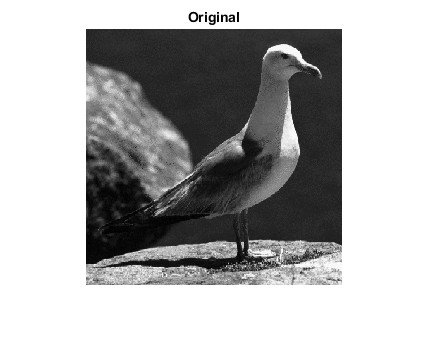

im = imread('gull.tif');
imshow(im), title ('Original')

### Soroll Gaussià

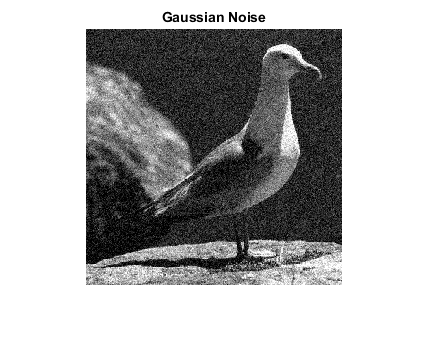

imgauss = imnoise(im, 'gaussian');
figure, imshow(imgauss), title('Gaussian Noise')

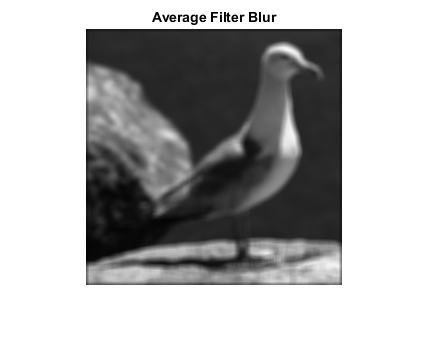


w = ones(7);
w = w/49;
resavg = imfilter(im, w, 'conv');
figure, imshow(resavg), title('Average Filter Blur')

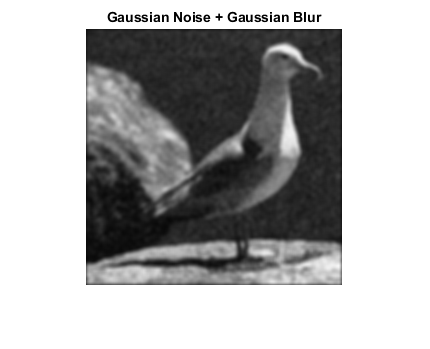


wgauss = fspecial('gaussian', 7, 2);
resgauss = imfilter(imgauss, wgauss, 'conv');
figure, imshow(resgauss), title('Gaussian Noise + Gaussian Blur')

### Soroll Salt & Pepper

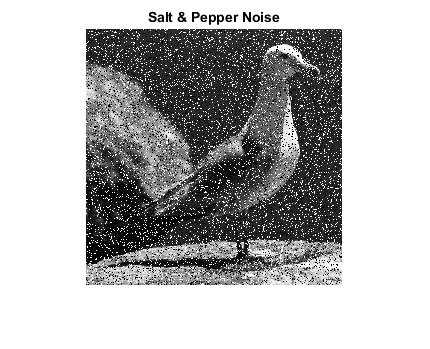

imsp = imnoise(im, 'salt & pepper', 0.2);
figure, imshow(imsp), title('Salt & Pepper Noise')

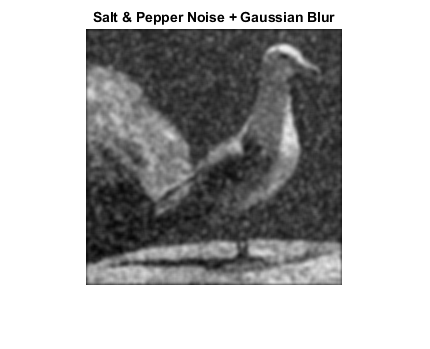


resgaus2 = imfilter(imsp, wgauss, 'conv');
figure, imshow(resgaus2), title('Salt & Pepper Noise + Gaussian Blur')

Filtre no lineal

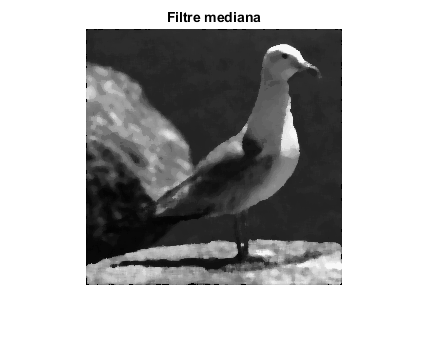

resmed = medfilt2(imsp, [5 5]);
figure, imshow(resmed), title('Filtre mediana')

## Resaltat de contorns

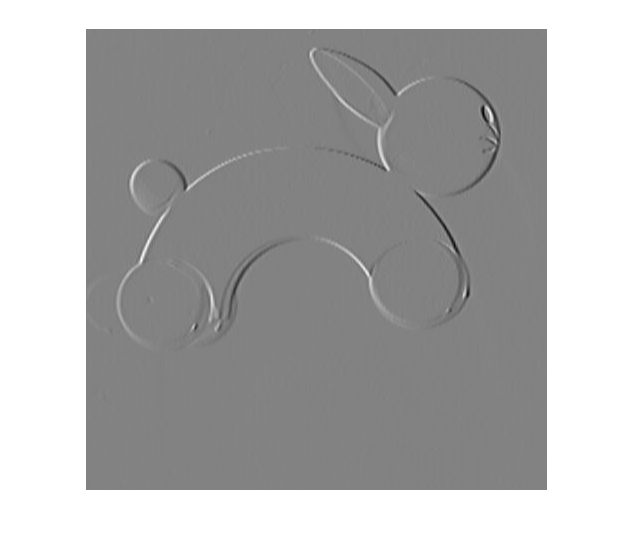

im = imread('rabbit.jpg');
novaim = zeros(size(im));
w = [-1 0 1;
     -1 0 1;
     -1 0 1];

for fila = 2:460
    for columna = 2:460
        mat3 = double(im((fila - 1):(fila + 1), (columna - 1):(columna + 1)));
        res = w .* mat3;
        novaim(fila, columna) = sum(res,'all');
    end
end
figure, imshow(novaim, [])

### Operador Sobel

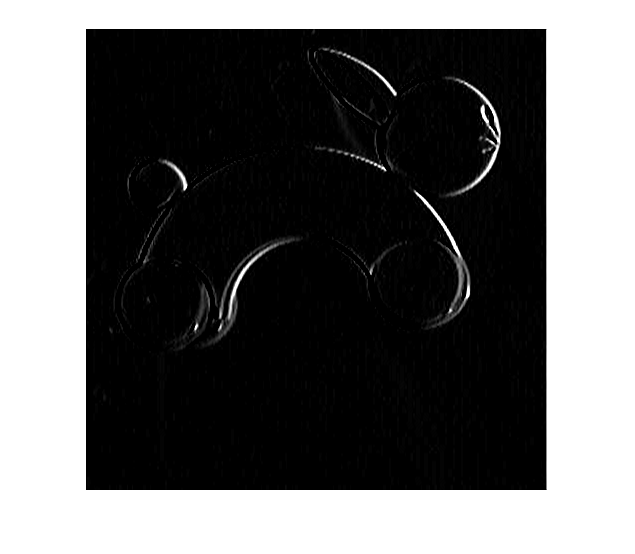

wx = [-1 0 1;
      -2 0 2;
      -1 0 1];
   
Gx = imfilter(im , wx, 'conv');
figure, imshow(Gx)

max(Gx(:))

ans = uint8
255

wx = wx/4

wx =    -0.2500         0    0.2500
   -0.5000         0    0.5000
   -0.2500         0    0.2500


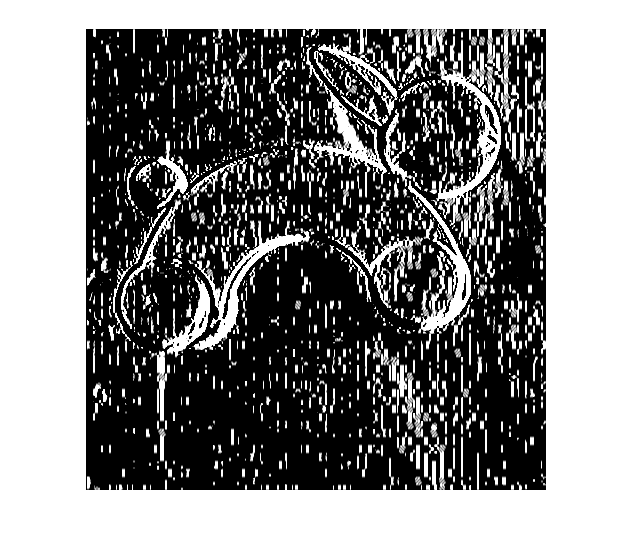

Gx = imfilter(double(im), wx, 'conv');
figure, imshow(Gx);

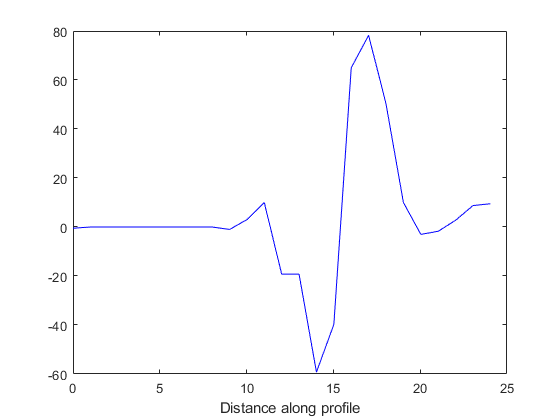


figure, imshow(Gx, []), title('Sobel vertical')
improfile

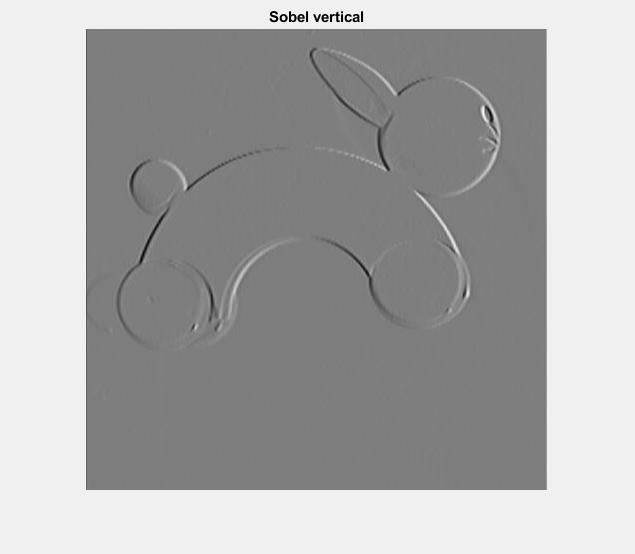

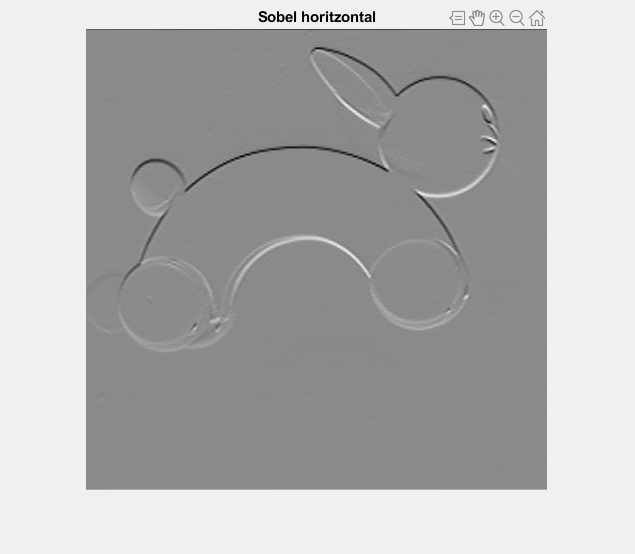

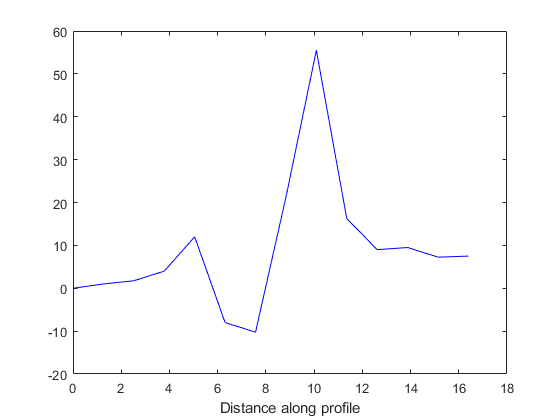

wy = wx';
Gy = imfilter(double(im), wy, 'conv');
figure, imshow(Gy, []), title('Sobel horitzontal')
improfile

## Mòdul i Direcció

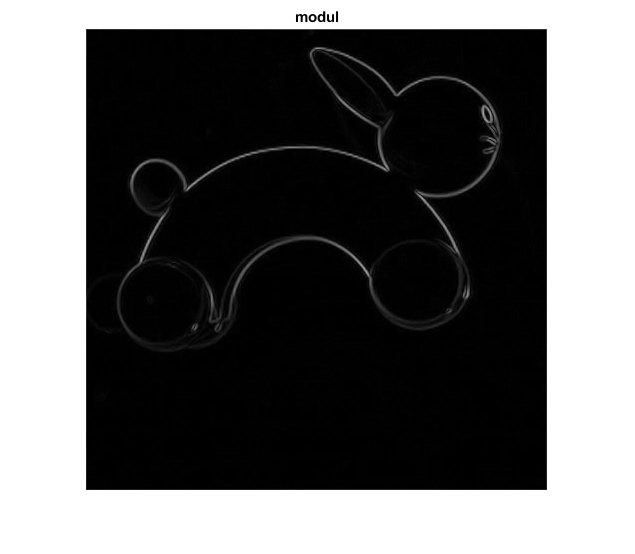

mod = sqrt(Gx.^2 + Gy.^2);
mod = uint8(mod);
figure, imshow(mod), title('modul')

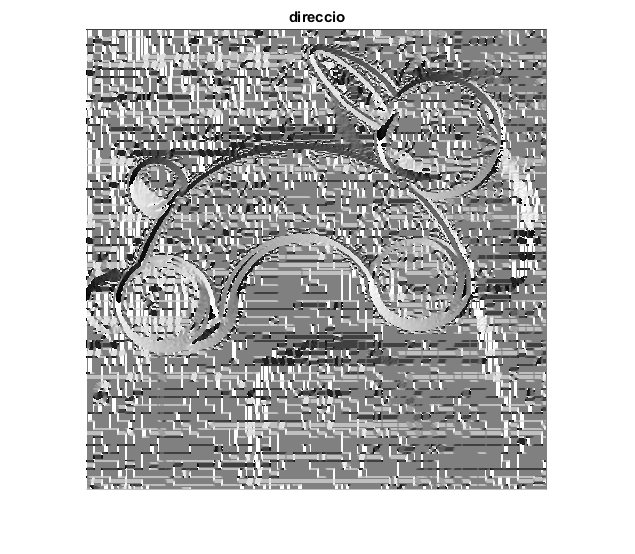

alfa = atan2(Gy, Gx);
alfa2 = uint8((alfa + pi)/2/pi * 255);
figure, imshow(alfa2), title('direccio')

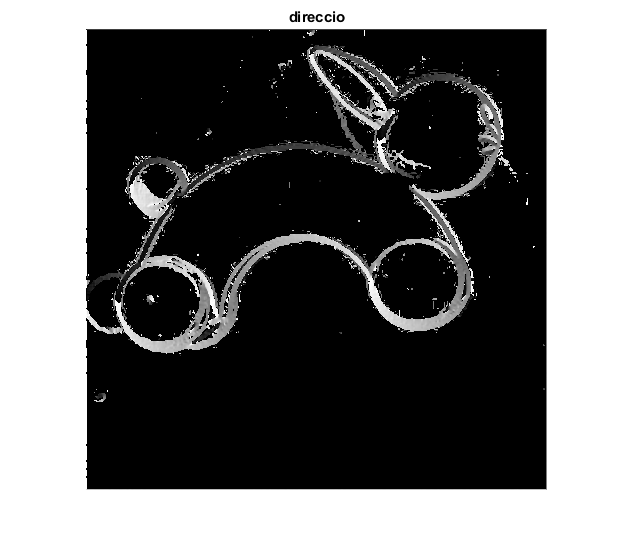

mask = mod < 4;
aux = alfa2;
aux(mask) = 0;
figure, imshow(aux), title('direccio')

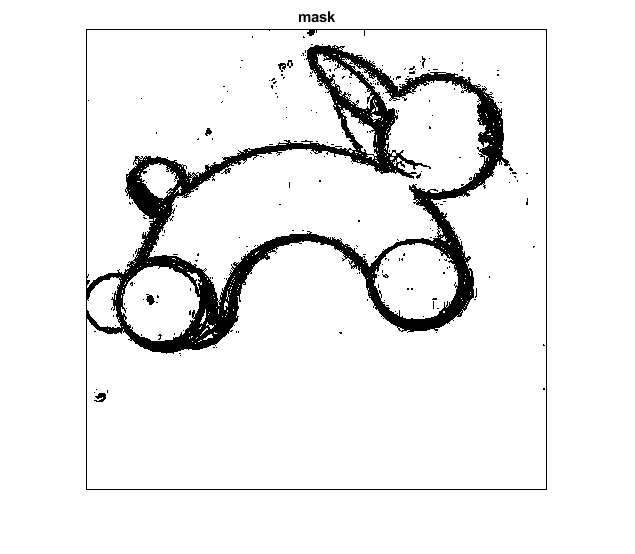

figure, imshow(mask), title('mask')

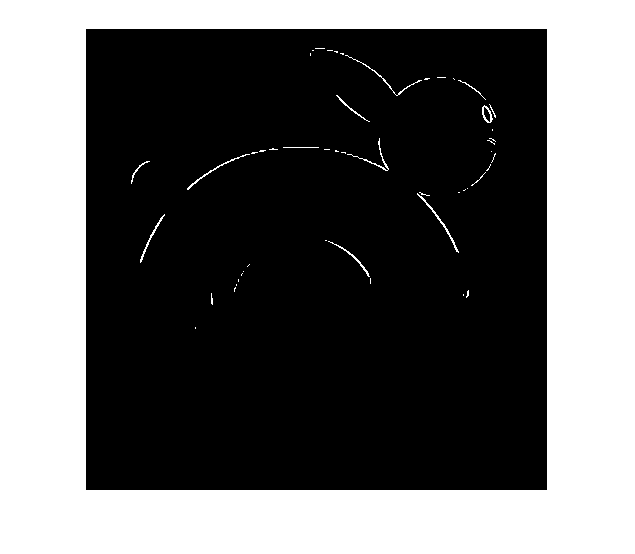

figure, imshow(mod > 90)